# Lab5

dt = 0.01;
df = dt;
t = -10 : dt : 10;
f = -15 : df : 15;

## Esercizio 1 (i)

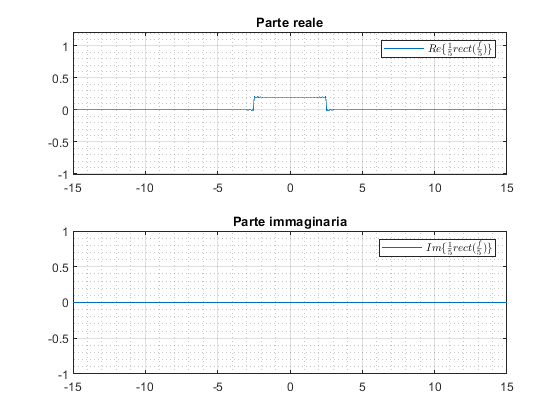

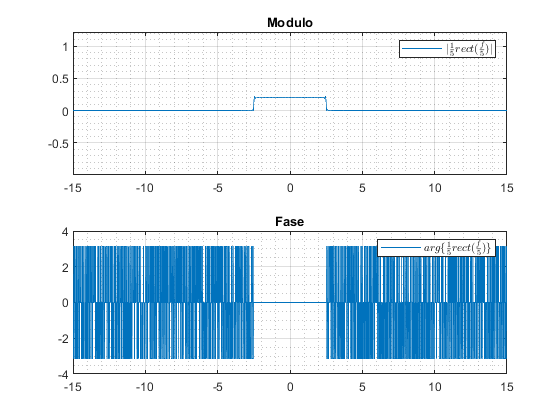

rappresentaUnSegnale(f, trasformataDiFourier(t, sinc(5 * t), f), '\frac{1}{5}rect(\frac{f}{5})');

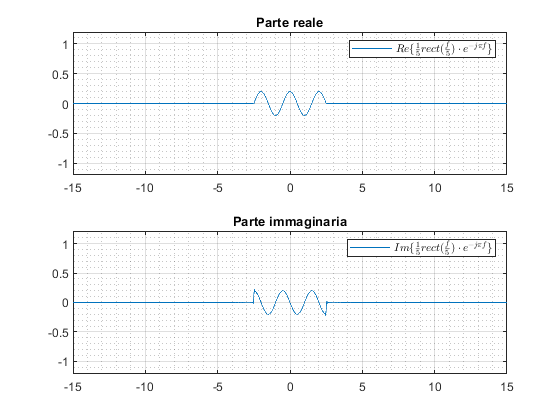

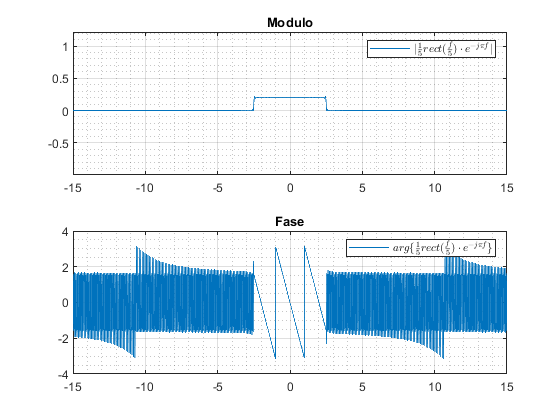

rappresentaUnSegnale(f, trasformataDiFourier(t, sinc(5 * (t - 1 / 2)), f), '\frac{1}{5}rect(\frac{f}{5})\cdot e^{-j\pi f}');

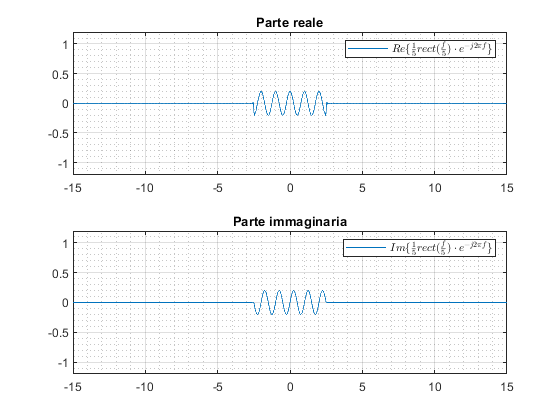

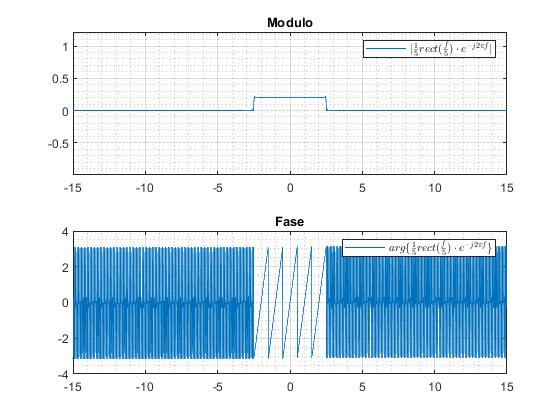

rappresentaUnSegnale(f, trasformataDiFourier(t, sinc(5 * (t + 1)), f), '\frac{1}{5}rect(\frac{f}{5})\cdot e^{-j2\pi f}');

## Esercizio 1 (ii)

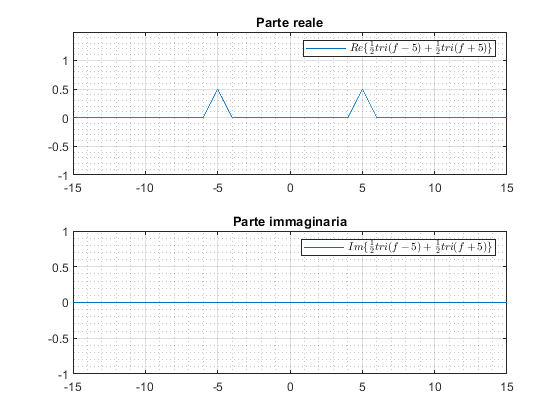

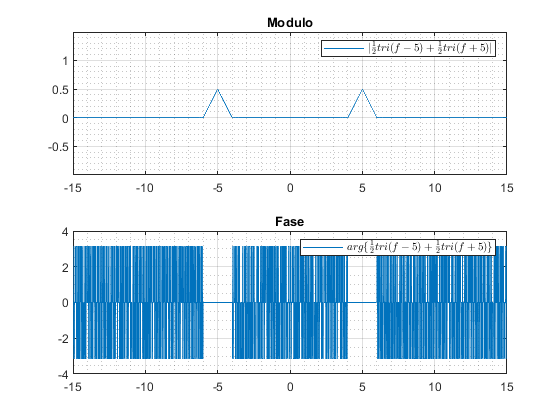

rappresentaUnSegnale(f, trasformataDiFourier(t, sinc(t).^2 .* cos(10 * pi * t), f), '\frac{1}{2}tri(f-5)+\frac{1}{2}tri(f+5)');

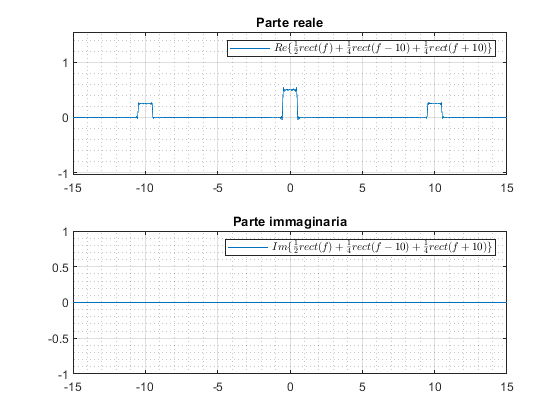

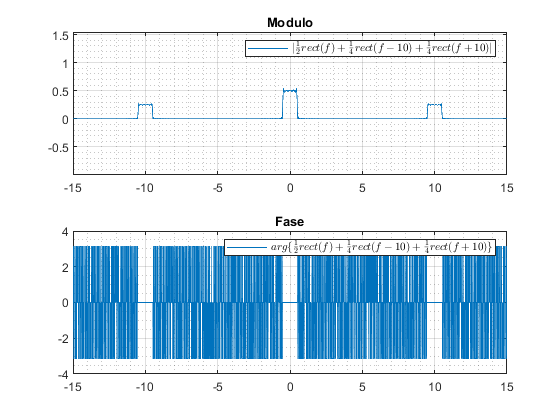

rappresentaUnSegnale(f, trasformataDiFourier(t, sinc(t) .* cos(10 * pi * t).^2, f), '\frac{1}{2}rect(f)+\frac{1}{4}rect(f-10)+\frac{1}{4}rect(f+10)');

## Esercizio 2 (i - ii)

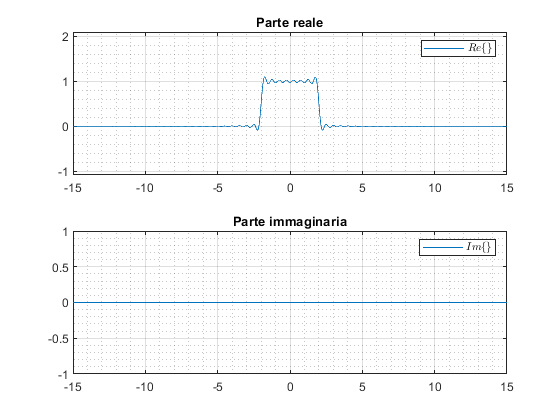

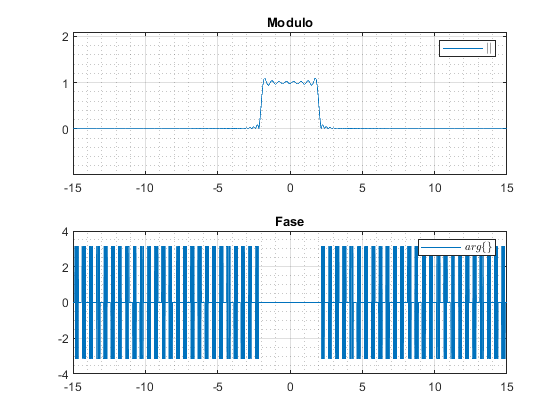

Energia errore H1 - H con B = 2: 4.575257e-02

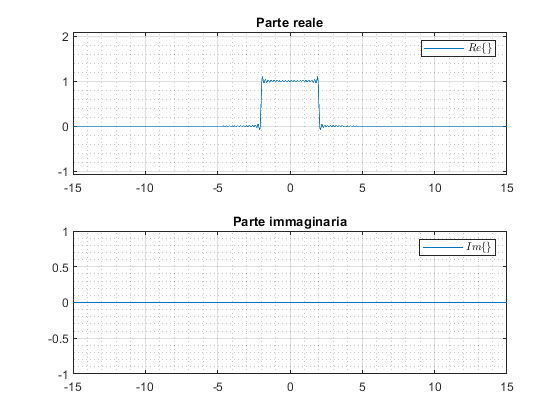

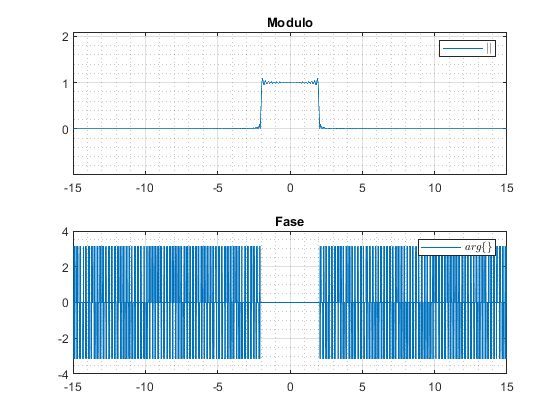

Energia errore H2 - H con B = 2: 1.559496e-02

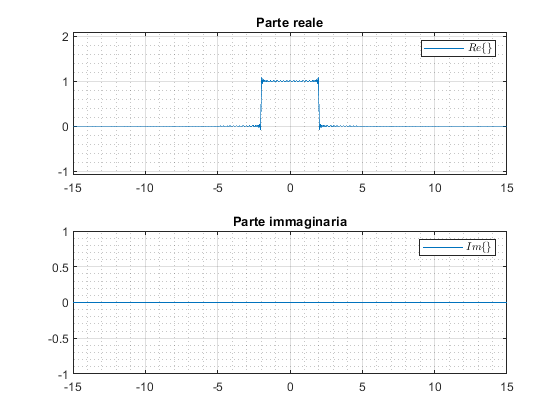

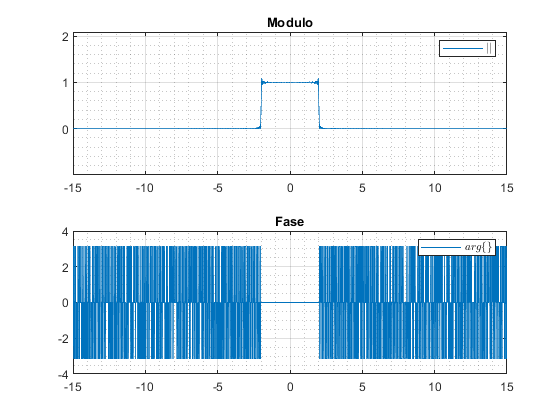

Energia errore H3 - H con B = 2: 5.799877e-03

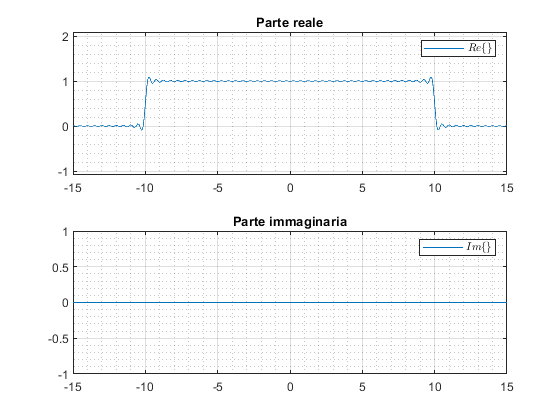

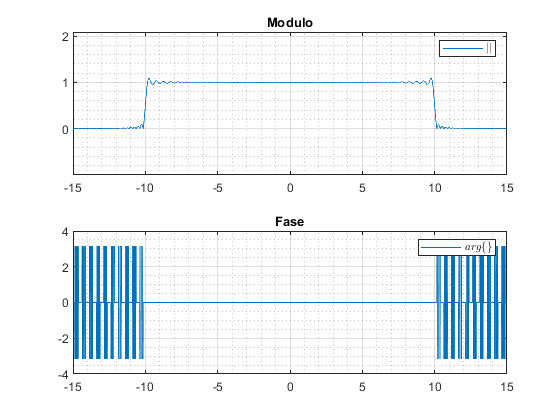

Energia errore H1 - H con B = 10: 4.572876e-02

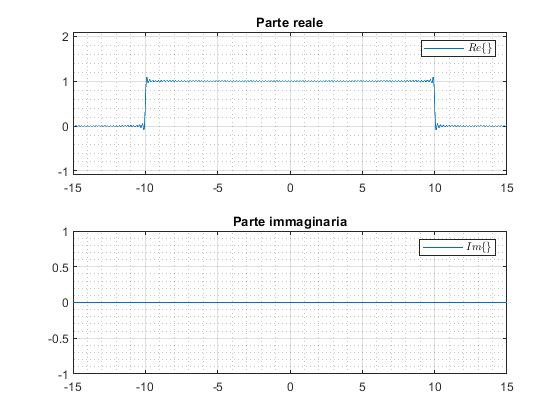

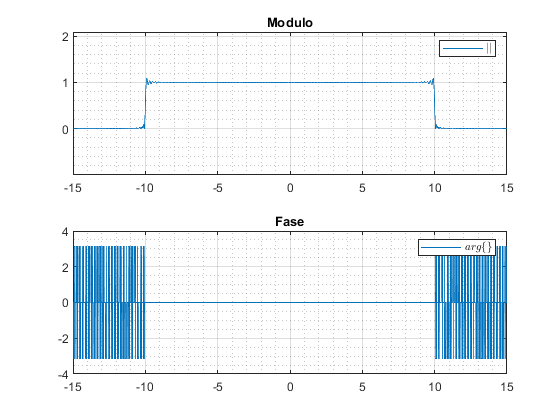

Energia errore H2 - H con B = 10: 1.558748e-02

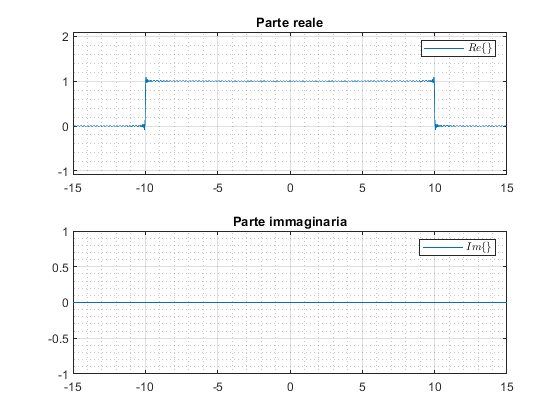

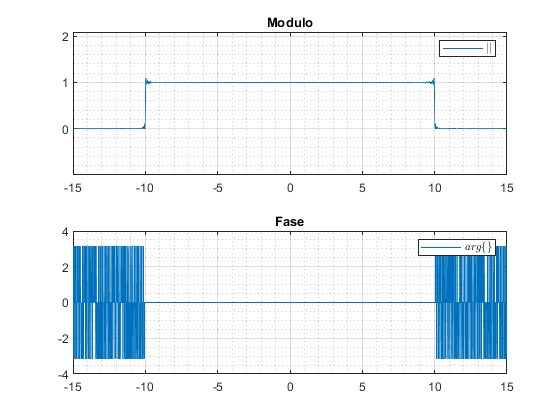

Energia errore H3 - H con B = 10: 5.797701e-03

for B = 2:8:10
	h = 2 * B * sinc(2 * B * t);
	H = rect(f / 2 / B);
	h1 = h .* rect(t / 4);
	H1 = trasformataDiFourier(t, h1, f);
	rappresentaUnSegnale(f, H1, '');
	energiaErr1 = energia(t, H1 - H);
	fprintf('Energia errore H1 - H con B = %d: %d', B, energiaErr1);
	h2 = h .* rect(t / 10);
	H2 = trasformataDiFourier(t, h2, f);
	rappresentaUnSegnale(f, H2, '');
	energiaErr2 = energia(t, H2 - H);
	fprintf('Energia errore H2 - H con B = %d: %d', B, energiaErr2);
	h3 = h .* rect(t / 20);
	H3 = trasformataDiFourier(t, h3, f);
	rappresentaUnSegnale(f, H3, '');
	energiaErr3 = energia(t, H3 - H);
	fprintf('Energia errore H3 - H con B = %d: %d', B, energiaErr3);
end

## Esercizio 3 (i)

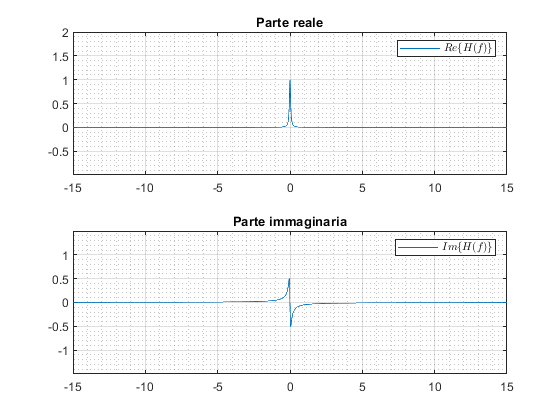

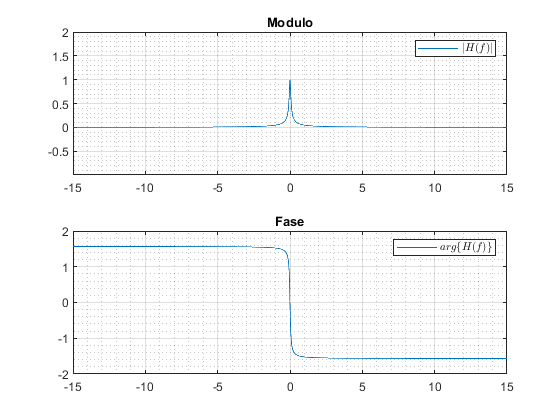

R = 3300;
C = 1 / 1000;
H = 1 ./ (1 + 1i * 2 * pi * f * R * C);
rappresentaUnSegnale(f, H, 'H(f)');

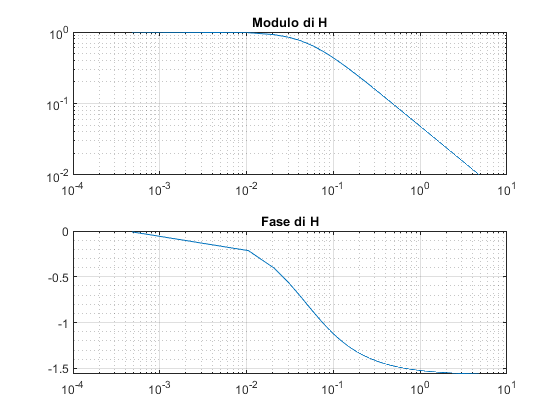

ft = 1 / (2 * pi * R * C);
flog = ft/100 : df : ft * 100;
Hlog = 1 ./ (1 + 1i * 2 * pi * flog * R * C);
figure;
subplot(2, 1, 1), loglog(flog, abs(Hlog)), title('Modulo di H'), grid on, grid minor;
subplot(2, 1, 2), semilogx(flog, angle(Hlog)), title('Fase di H'), grid on, grid minor;

## Esercizio 3 (iii)

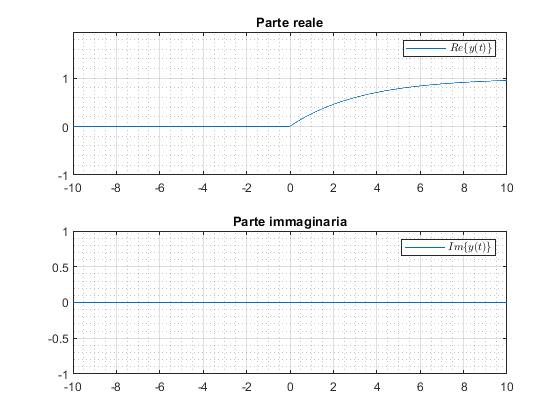

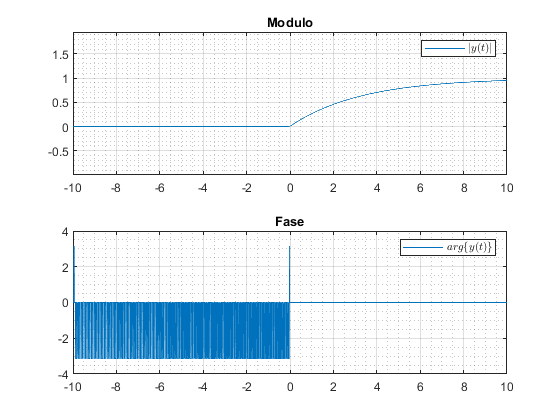

	h = antitrasformataDiFourier(f, H, t);
	y = convoluzione(t, gradino(t), h);
	rappresentaUnSegnale(y(1, :), y(2, :), 'y(t)');